# **Computational Assignment 2**

**EE4140 - Digital Communication Systems**

**Jayadev Joy (EE18B011) **

***Department of Electrical Engineering, IIT Madras***

*24 November 2022*

*I certify that this experiment submission is my own work and not obtained from any other source.*

## 1. Initializing the system parameters

len = 10000;
Es = 1;

F_z = (1/sqrt(2))*[0.8 -1 0.6];
G_z = (1/1.4916)*[1 -0.95 0.5 0.15 -0.2 -0.1];
L_1 = length(F_z);
L_2 = length(G_z);

SNRdB_1 = 0:2:16;
SNR_1 = 10.^(SNRdB_1/10);
sigma_1 = sqrt(Es./SNR_1);
delay_1 = [3 6 10 20 40];

SNRdB_2 = 0:4:28;
SNR_2 = 10.^(SNRdB_2/10);
sigma_2 = sqrt(Es./SNR_2);
delay_2 = 30;

signal = binornd(1,0.5,[1 (2*len)]);
symbols_4pam = zeros([1 len]);
for i = 1:len
    if (signal(2*i-1) == 1) && (signal(2*i) == 1)
        symbols_4pam(i) = -3;
    elseif (signal(2*i-1) == 1) && (signal(2*i) == 0)
        symbols_4pam(i) = -1;
    elseif (signal(2*i-1) == 0) && (signal(2*i) == 0)
        symbols_4pam(i) = 1;
    elseif (signal(2*i-1) == 0) && (signal(2*i) == 1)
        symbols_4pam(i) = 3;
    end
end

signal = binornd(1,0.5,[1 len]);
symbols_2pam = zeros([1 len]);
for i = 1:len
    if signal(i) == 0
        symbols_2pam(i) = -1;
    else
        symbols_2pam(i) = 1;
    end
end

r_4pam = zeros([1 len+L_1-1]);
for i = 1:length(r_4pam)
    if (i == 1)
        r_4pam(i) = F_z(1)*symbols_4pam(1) + F_z(2) + F_z(3);
    elseif (i == 2)
        r_4pam(i) = F_z(1)*symbols_4pam(2) + F_z(2)*symbols_4pam(1) + F_z(3);
    elseif (i == (len+1))
        r_4pam(i) = F_z(1) + F_z(2)*symbols_4pam(len) + F_z(3)*symbols_4pam(len-1);
    elseif (i == (len+2))
        r_4pam(i) = F_z(1) + F_z(2) + F_z(3)*symbols_4pam(len);        
    else
        r_4pam(i) = F_z(1)*symbols_4pam(i) + F_z(2)*symbols_4pam(i-1) + F_z(3)*symbols_4pam(i-2);
    end
end

r_2pam = zeros([1 len+L_2-1]);
for i = 1:length(r_2pam)
    if (i == 1)
        r_2pam(i) = G_z(1)*symbols_2pam(1) + G_z(2) + G_z(3) + G_z(4) + G_z(5) + G_z(6);
    elseif (i == 2)
        r_2pam(i) = G_z(1)*symbols_2pam(2) + G_z(2)*symbols_2pam(1) + G_z(3) + G_z(4) + G_z(5) + G_z(6);
    elseif (i == 3)
        r_2pam(i) = G_z(1)*symbols_2pam(3) + G_z(2)*symbols_2pam(2) + G_z(3)*symbols_2pam(1) + G_z(4) + G_z(5) + G_z(6);
    elseif (i == 4)
        r_2pam(i) = G_z(1)*symbols_2pam(4) + G_z(2)*symbols_2pam(3) + G_z(3)*symbols_2pam(2) + G_z(4)*symbols_2pam(1) + G_z(5) + G_z(6);
    elseif (i == 5)
        r_2pam(i) = G_z(1)*symbols_2pam(5) + G_z(2)*symbols_2pam(4) + G_z(3)*symbols_2pam(3) + G_z(4)*symbols_2pam(2) + G_z(5)*symbols_2pam(1) + G_z(6);
    elseif (i == (len+1))
        r_2pam(i) = G_z(1) + G_z(2)*symbols_2pam(len) + G_z(3)*symbols_2pam(len-1) + G_z(4)*symbols_2pam(len-2) + G_z(5)*symbols_2pam(len-3) + G_z(6)*symbols_2pam(len-4);
    elseif (i == (len+2))
        r_2pam(i) = G_z(1) + G_z(2) + G_z(3)*symbols_2pam(len) + G_z(4)*symbols_2pam(len-1) + G_z(5)*symbols_2pam(len-2) + G_z(6)*symbols_2pam(len-3); 
    elseif (i == (len+3))
        r_2pam(i) = G_z(1) + G_z(2) + G_z(3) + G_z(4)*symbols_2pam(len) + G_z(5)*symbols_2pam(len-1) + G_z(6)*symbols_2pam(len-2);
    elseif (i == (len+4))
        r_2pam(i) = G_z(1) + G_z(2) + G_z(3) + G_z(4) + G_z(5)*symbols_2pam(len) + G_z(6)*symbols_2pam(len-1);
    elseif (i == (len+5))
        r_2pam(i) = G_z(1) + G_z(2) + G_z(3) + G_z(4) + G_z(5) + G_z(6)*symbols_2pam(len);        
    else
        r_2pam(i) = G_z(1)*symbols_2pam(i) + G_z(2)*symbols_2pam(i-1) + G_z(3)*symbols_2pam(i-2) + G_z(4)*symbols_2pam(i-3) + G_z(5)*symbols_2pam(i-4) + G_z(6)*symbols_2pam(i-5);
    end
end

ser_delay_1_1 = zeros([1 length(sigma_1)]);
ser_delay_1_2 = zeros([1 length(sigma_1)]);
ser_delay_1_3 = zeros([1 length(sigma_1)]);
ser_delay_1_4 = zeros([1 length(sigma_1)]);
ser_delay_1_5 = zeros([1 length(sigma_1)]);
ser_delay_2_1 = zeros([1 length(sigma_2)]);
ser_delay_2_2 = zeros([1 length(sigma_2)]);

## 2. VA based sequence estimator for FIR channel with L = 3 taps

for x = 1:length(sigma_1)
    
    r_4pam_rec = r_4pam + normrnd(0,sigma_1(x),[1 length(r_4pam)]);
        
    seq_delay_1 = zeros([1 length(r_4pam)]);
    seq_delay_2 = zeros([1 length(r_4pam)]);
    seq_delay_3 = zeros([1 length(r_4pam)]);
    seq_delay_4 = zeros([1 length(r_4pam)]);
    seq_delay_5 = zeros([1 length(r_4pam)]);

    seq_trl_old = zeros([16 length(r_4pam)]);
    seq_trl_new = zeros([16 length(r_4pam)]);
    
    cm_old = zeros([1 16]);
    cm_new = zeros([1 16]);
    
    pam_4 = [-3 -1 1 3];
    pam_4_metric = zeros([1 length(pam_4)]);  
    
    for y = 1:length(r_4pam)
        if (y == 1)
            for i = 1:length(pam_4)
                cm_old(4*i-1) = (F_z(1)*pam_4(i) + F_z(2) + F_z(3) - r_4pam_rec(1)).^2;
                seq_trl_old(4*i-1,1) = pam_4(i);
            end
        elseif (y == 2)
            for i = 1:length(pam_4)
                for j = 1:length(pam_4)
                    cm_new(4*i+j-4) = cm_old(4*j-1) + (F_z(1)*pam_4(i) + F_z(2)*pam_4(j) + F_z(3) - r_4pam_rec(2)).^2;
                    seq_trl_new(4*i+j-4,1) = seq_trl_old(4*j-1,1);
                    seq_trl_new(4*i+j-4,2) = pam_4(i);
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == (len+1))
            for j = 1:length(pam_4)
                for k = 1:length(pam_4)
                    pam_4_metric(k) = cm_old(4*j+k-4) + (F_z(1) + F_z(2)*pam_4(j) + F_z(3)*pam_4(k) - r_4pam_rec(y)).^2;
                end
                k_hat = find(pam_4_metric==min(pam_4_metric));
                cm_new(8+j) = min(pam_4_metric);
                seq_trl_new(8+j,1:y) = seq_trl_old(4*j+k_hat-4,1:y);
                seq_trl_new(8+j,y) = pam_4(3);
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == (len+2))
            for k = 1:length(pam_4)
                pam_4_metric(k) = cm_old(8+k) + (F_z(1) + F_z(2) + F_z(3)*pam_4(k) - r_4pam_rec(y)).^2;
            end
            k_hat = find(pam_4_metric==min(pam_4_metric));
            cm_new(11) = min(pam_4_metric);
            seq_trl_new(11,1:y) = seq_trl_old(8+k_hat,1:y);
            seq_trl_new(11,y) = pam_4(i);
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;            
        else
            for i = 1:length(pam_4)
                for j = 1:length(pam_4)
                    for k = 1:length(pam_4)
                        pam_4_metric(k) = cm_old(4*j+k-4) + (F_z(1)*pam_4(i) + F_z(2)*pam_4(j) + F_z(3)*pam_4(k) - r_4pam_rec(y)).^2;
                    end
                    k_hat = find(pam_4_metric==min(pam_4_metric));
                    cm_new(4*i+j-4) = min(pam_4_metric);
                    seq_trl_new(4*i+j-4,1:y) = seq_trl_old(4*j+k_hat-4,1:y);
                    seq_trl_new(4*i+j-4,y) = pam_4(i);
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        end

        if (y > delay_1(1) && y < (len+1))
            seq_delay_1(y-delay_1(1)) = seq_trl_old(find(cm_old==min(cm_old)),y-delay_1(1));
        end
        if (y > delay_1(2) && y < (len+1))
            seq_delay_2(y-delay_1(2)) = seq_trl_old(find(cm_old==min(cm_old)),y-delay_1(2));
        end
        if (y > delay_1(3) && y < (len+1))
            seq_delay_3(y-delay_1(3)) = seq_trl_old(find(cm_old==min(cm_old)),y-delay_1(3));
        end
        if (y > delay_1(4) && y < (len+1))
            seq_delay_4(y-delay_1(4)) = seq_trl_old(find(cm_old==min(cm_old)),y-delay_1(4));
        end
        if (y > delay_1(5) && y < (len+1))
            seq_delay_5(y-delay_1(5)) = seq_trl_old(find(cm_old==min(cm_old)),y-delay_1(5));
        end
        if (y == (len+2))
            seq_delay_1((len+1-delay_1(1)):end) = seq_trl_old(11,(len+1-delay_1(1)):end);
            seq_delay_2((len+1-delay_1(2)):end) = seq_trl_old(11,(len+1-delay_1(2)):end);
            seq_delay_3((len+1-delay_1(3)):end) = seq_trl_old(11,(len+1-delay_1(3)):end);
            seq_delay_4((len+1-delay_1(4)):end) = seq_trl_old(11,(len+1-delay_1(4)):end);
            seq_delay_5((len+1-delay_1(5)):end) = seq_trl_old(11,(len+1-delay_1(5)):end);
        end
    
    ser_delay_1_1(x) = err(symbols_4pam, seq_delay_1(1:len));
    ser_delay_1_2(x) = err(symbols_4pam, seq_delay_2(1:len));
    ser_delay_1_3(x) = err(symbols_4pam, seq_delay_3(1:len));
    ser_delay_1_4(x) = err(symbols_4pam, seq_delay_4(1:len));
    ser_delay_1_5(x) = err(symbols_4pam, seq_delay_5(1:len));

    end
end

## 3. VA based sequence estimator for FIR channel with L = 6 taps (32 Trellis states)

for x = 1:length(sigma_2)
    
    r_2pam_rec = r_2pam + normrnd(0,sigma_2(x),[1 length(r_2pam)]);
        
    seq_delay = zeros([1 length(r_2pam)]);

    seq_trl_old = zeros([32 length(r_2pam)]);
    seq_trl_new = zeros([32 length(r_2pam)]);
    
    cm_old = zeros([1 32]);
    cm_new = zeros([1 32]);
    
    pam_2 = [-1 1];
    pam_2_metric = zeros([1 length(pam_2)]);  
    
    for y = 1:length(r_2pam)
        if (y == 1)
            for i = 1:length(pam_2)
                cm_old(16*i) = (G_z(1)*pam_2(i) + G_z(2) + G_z(3) + G_z(4) + G_z(5) + G_z(6)- r_2pam_rec(y)).^2;
                seq_trl_old(16*i,y) = pam_2(i);
            end
        elseif (y == 2)
            k = 2; l = 2; m = 2; n = 2;
            for i = 1:length(pam_2)
                for j = 1:length(pam_2)
                    cm_new(16*i+8*j+4*k+2*l+m-30) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1)*pam_2(i) + G_z(2)*pam_2(j) + G_z(3) + G_z(4) + G_z(5) + G_z(6) - r_2pam_rec(y)).^2;
                    seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n-30,1:y);
                    seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);                                
                end                          
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == 3)
            l = 2; m = 2; n = 2;
            for i = 1:length(pam_2)
                for j = 1:length(pam_2)
                    for k = 1:length(pam_2)   
                        cm_new(16*i+8*j+4*k+2*l+m-30) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1)*pam_2(i) + G_z(2)*pam_2(j) + G_z(3)*pam_2(k) + G_z(4) + G_z(5) + G_z(6) - r_2pam_rec(y)).^2;
                        seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n-30,1:y);
                        seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
                    end
                end                          
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == 4)
            m = 2; n = 2;
            for i = 1:length(pam_2)
                for j = 1:length(pam_2)
                    for k = 1:length(pam_2)
                        for l = 1:length(pam_2)
                            cm_new(16*i+8*j+4*k+2*l+m-30) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1)*pam_2(i) + G_z(2)*pam_2(j) + G_z(3)*pam_2(k) + G_z(4)*pam_2(l) + G_z(5) + G_z(6) - r_2pam_rec(y)).^2;
                            seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n-30,1:y);
                            seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
                        end
                    end
                end                          
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == 5)
            n = 2;
            for i = 1:length(pam_2)
                for j = 1:length(pam_2)
                    for k = 1:length(pam_2)
                        for l = 1:length(pam_2)
                            for m = 1:length(pam_2)
                                cm_new(16*i+8*j+4*k+2*l+m-30) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1)*pam_2(i) + G_z(2)*pam_2(j) + G_z(3)*pam_2(k) + G_z(4)*pam_2(l) + G_z(5)*pam_2(m) + G_z(6) - r_2pam_rec(y)).^2;
                                seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n-30,1:y);
                                seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
                            end
                        end
                    end
                end                          
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;       
        elseif (y == (len+1))
            i = 2;
            for j = 1:length(pam_2)
                for k = 1:length(pam_2)
                    for l = 1:length(pam_2)
                        for m = 1:length(pam_2)
                            for n = 1:length(pam_2)
                                pam_2_metric(n) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1) + G_z(2)*pam_2(j) + G_z(3)*pam_2(k) + G_z(4)*pam_2(l) + G_z(5)*pam_2(m) + G_z(6)*pam_2(n)- r_2pam_rec(y)).^2;
                            end
                            n_hat = find(pam_2_metric==min(pam_2_metric));
                            cm_new(16*i+8*j+4*k+2*l+m-30) = min(pam_2_metric);
                            seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n_hat-30,1:y);
                            seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
                        end
                    end
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == (len+2))
            i = 2; j = 2;
            for k = 1:length(pam_2)
                for l = 1:length(pam_2)
                    for m = 1:length(pam_2)
                        for n = 1:length(pam_2)
                            pam_2_metric(n) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1) + G_z(2) + G_z(3)*pam_2(k) + G_z(4)*pam_2(l) + G_z(5)*pam_2(m) + G_z(6)*pam_2(n)- r_2pam_rec(y)).^2;
                        end
                        n_hat = find(pam_2_metric==min(pam_2_metric));
                        cm_new(16*i+8*j+4*k+2*l+m-30) = min(pam_2_metric);
                        seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n_hat-30,1:y);
                        seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
                    end
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new; 
        elseif (y == (len+3))
            i = 2; j = 2; k = 2;
            for l = 1:length(pam_2)
                for m = 1:length(pam_2)
                    for n = 1:length(pam_2)
                        pam_2_metric(n) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1) + G_z(2) + G_z(3) + G_z(4)*pam_2(l) + G_z(5)*pam_2(m) + G_z(6)*pam_2(n)- r_2pam_rec(y)).^2;
                    end
                    n_hat = find(pam_2_metric==min(pam_2_metric));
                    cm_new(16*i+8*j+4*k+2*l+m-30) = min(pam_2_metric);
                    seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n_hat-30,1:y);
                    seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;         
        elseif (y == (len+4))
            i = 2; j = 2; k = 2; l = 2;
            for m = 1:length(pam_2)
                for n = 1:length(pam_2)
                    pam_2_metric(n) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1) + G_z(2) + G_z(3) + G_z(4) + G_z(5)*pam_2(m) + G_z(6)*pam_2(n)- r_2pam_rec(y)).^2;
                end
                n_hat = find(pam_2_metric==min(pam_2_metric));
                cm_new(16*i+8*j+4*k+2*l+m-30) = min(pam_2_metric);
                seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n_hat-30,1:y);
                seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == (len+5))
            i = 2; j = 2; k = 2; l = 2; m = 2;
            for n = 1:length(pam_2)
                pam_2_metric(n) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1) + G_z(2) + G_z(3) + G_z(4) + G_z(5) + G_z(6)*pam_2(n)- r_2pam_rec(y)).^2;
            end
            n_hat = find(pam_2_metric==min(pam_2_metric));
            cm_new(16*i+8*j+4*k+2*l+m-30) = min(pam_2_metric);
            seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n_hat-30,1:y);
            seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;                        
        else
            for i = 1:length(pam_2)
                for j = 1:length(pam_2)
                    for k = 1:length(pam_2)
                        for l = 1:length(pam_2)
                            for m = 1:length(pam_2)
                                for n = 1:length(pam_2)
                                    pam_2_metric(n) = cm_old(16*j+8*k+4*l+2*m+n-30) + (G_z(1)*pam_2(i) + G_z(2)*pam_2(j) + G_z(3)*pam_2(k) + G_z(4)*pam_2(l) + G_z(5)*pam_2(m) + G_z(6)*pam_2(n)- r_2pam_rec(y)).^2;
                                end
                                n_hat = find(pam_2_metric==min(pam_2_metric));
                                cm_new(16*i+8*j+4*k+2*l+m-30) = min(pam_2_metric);
                                seq_trl_new(16*i+8*j+4*k+2*l+m-30,1:y) = seq_trl_old(16*j+8*k+4*l+2*m+n_hat-30,1:y);
                                seq_trl_new(16*i+8*j+4*k+2*l+m-30,y) = pam_2(i);
                            end
                        end
                    end
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        end

        if (y > delay_2 && y < (len+1))
            seq_delay(y-delay_2) = seq_trl_old(find(cm_old==min(cm_old)),y-delay_2);
        end
        if (y == (len+5))
            seq_delay((len+1-delay_2):end) = seq_trl_old(32,(len+1-delay_2):end);
        end
    
    ser_delay_2_1(x) = err(symbols_2pam, seq_delay(1:len));

    end
end

## 4. VA based sequence estimator for FIR channel with L = 6 taps (4 Trellis states)

for x = 1:length(sigma_2)
    
    r_2pam_rec = r_2pam + normrnd(0,sigma_2(x),[1 length(r_2pam)]);
        
    seq_delay = zeros([1 length(r_2pam)]);

    seq_trl_old = zeros([4 length(r_2pam)]);
    seq_trl_new = zeros([4 length(r_2pam)]);
    
    cm_old = zeros([1 4]);
    cm_new = zeros([1 4]);
    
    pam_2 = [-1 1];
    pam_2_metric = zeros([1 length(pam_2)]);  
    
    for y = 1:length(r_2pam)
        if (y == 1)
            for i = 1:length(pam_2)
                cm_old(2*i) = (G_z(1)*pam_2(i) + G_z(2) + G_z(3) - r_2pam_rec(1)).^2;
                seq_trl_old(2*i,1) = pam_2(i);
            end
        elseif (y == 2)
            for i = 1:length(pam_2)
                for j = 1:length(pam_2)
                    cm_new(2*i+j-2) = cm_old(2*j) + (G_z(1)*pam_2(i) + G_z(2)*pam_2(j) + G_z(3) - r_2pam_rec(2)).^2;
                    seq_trl_new(2*i+j-2,1) = seq_trl_old(2*j,1);
                    seq_trl_new(2*i+j-2,2) = pam_2(i);
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == (len+1))
            i = 2;
            for j = 1:length(pam_2)
                for k = 1:length(pam_2)
                    pam_2_metric(k) = cm_old(2*j+k-2) + (G_z(1) + G_z(2)*pam_2(j) + G_z(3)*pam_2(k) - r_2pam_rec(y)).^2;
                end
                k_hat = find(pam_2_metric==min(pam_2_metric));
                cm_new(2*i+j-2) = min(pam_2_metric);
                seq_trl_new(2*i+j-2,1:y) = seq_trl_old(2*j+k_hat-2,1:y);
                seq_trl_new(2*i+j-2,y) = pam_2(i);
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        elseif (y == (len+2))
            i = 2; j = 2;
            for k = 1:length(pam_2)
                pam_2_metric(k) = cm_old(2*j+k-2) + (G_z(1) + G_z(2) + G_z(3)*pam_2(k) - r_2pam_rec(y)).^2;
            end
            k_hat = find(pam_2_metric==min(pam_2_metric));
            cm_new(2*i+j-2) = min(pam_2_metric);
            seq_trl_new(2*i+j-2,1:y) = seq_trl_old(2*j+k_hat-2,1:y);
            seq_trl_new(2*i+j-2,y) = pam_2(i);
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;            
        else
            for i = 1:length(pam_2)
                for j = 1:length(pam_2)
                    for k = 1:length(pam_2)
                        pam_2_metric(k) = cm_old(2*j+k-2) + (G_z(1)*pam_2(i) + G_z(2)*pam_2(j) + G_z(3)*pam_2(k) - r_2pam_rec(y)).^2;
                    end
                    k_hat = find(pam_2_metric==min(pam_2_metric));
                    cm_new(2*i+j-2) = min(pam_2_metric);
                    seq_trl_new(2*i+j-2,1:y) = seq_trl_old(2*j+k_hat-2,1:y);
                    seq_trl_new(2*i+j-2,y) = pam_2(i);
                end
            end
            cm_old = cm_new;
            seq_trl_old = seq_trl_new;
        end

        if (y > delay_2 && y < (len+1))
            seq_delay(y-delay_2) = seq_trl_old(find(cm_old==min(cm_old)),y-delay_2);
        end
        if (y == (len+2))
            seq_delay((len+1-delay_2):end) = seq_trl_old(4,(len+1-delay_2):end);
        end
    
    ser_delay_2_2(x) = err(symbols_2pam, seq_delay(1:len));

    end
end

## 5. Experimental SER of VA based sequence estimator (L = 3) for different values of $\delta$

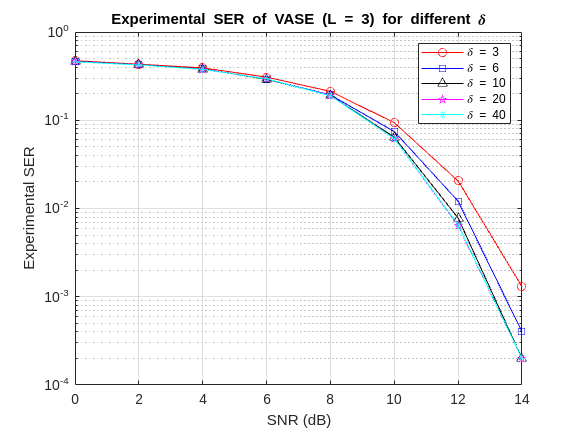

figure(1)
semilogy(SNRdB_1,ser_delay_1_1,'-or')
hold on
semilogy(SNRdB_1,ser_delay_1_2,'-sb')
hold on
semilogy(SNRdB_1,ser_delay_1_3,'-^k')
hold on
semilogy(SNRdB_1,ser_delay_1_4,'-pm')
hold on
semilogy(SNRdB_1,ser_delay_1_5,'-*c')
grid on
title('Experimental SER of VASE (L = 3) for different \delta')
xlabel('SNR (dB)')
ylabel('Experimental SER')
legend('\delta = 3','\delta = 6','\delta = 10','\delta = 20','\delta = 40')
hold off

## 6. Experimental SER of VA based sequence estimator (L = 6)

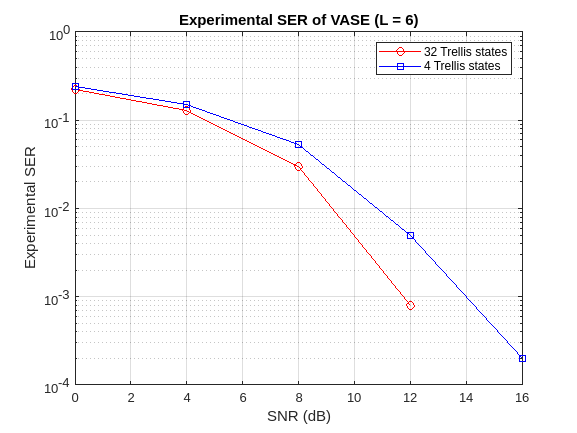

figure(2)
semilogy(SNRdB_2,ser_delay_2_1,'-or')
hold on
semilogy(SNRdB_2,ser_delay_2_2,'-sb')
grid on
title('Experimental SER of VASE (L = 6)')
xlabel('SNR (dB)')
ylabel('Experimental SER')
legend('32 Trellis states','4 Trellis states')
hold off

## 7. Functions used in the simulations

function x = err(sym_org, sym_est)
    x = sum(sym_org ~= sym_est)/length(sym_org);
end